## Stereo multiview 3D reconstruction

### Data preparation

A sequence of images is loaded from a specified directory using the `imageDatastore` function. It then creates a montage of the images using the `montage` function and displays it in a figure window. The images are then converted to grayscale and stored in a cell array. Finally, it loads the `stereoParams` structure from a file and stores the `CameraParameters1` field in the `cameraParams` variable

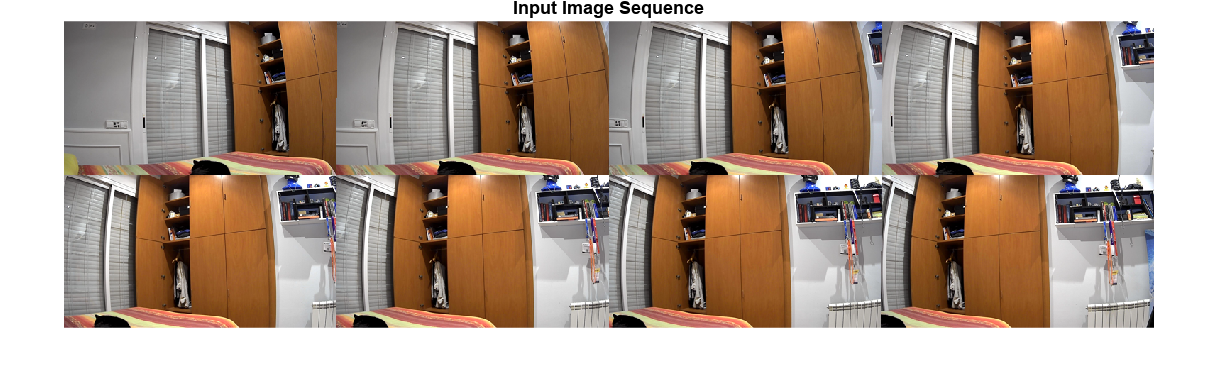

clc;
clear all;

% Set the directory where the images are located
imageDir = fullfile('Scripts/images/Left_habitacion/');

% Load the images using the imageDatastore function
imds = imageDatastore(imageDir);

% Get the number of images and columns in the dataset
[n_img, colu] = size(imds.Files);


figure
% Create a montage of the images using the montage function
% The montage will be 2 rows and n_img/2 columns
montage(imds.Files, 'Size', [2, n_img/2]);

% Add a title to the figure
title('Input Image Sequence');

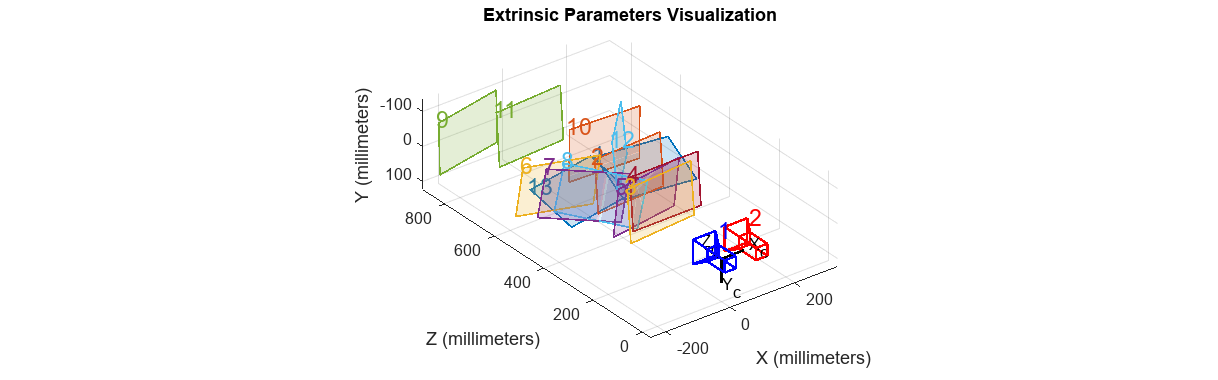


% Convert the images to grayscale
images = cell(1, numel(imds.Files));
for i = 1:numel(imds.Files)
    % Read the i-th image
    I = readimage(imds, i);

    % Convert the image to grayscale
    images{i} = rgb2gray(I);
end

% Load the stereoParams structure from a file
load('resources/habitacion_reconstruction/stereoParams.mat');

% Store the CameraParameters1 field in the cameraParams variable
cameraParams = stereoParams.CameraParameters1;
showExtrinsics(stereoParams);

### Estimation of camera 3D poses

#### 1st frame extraction

The first part of the code reads the intrinsic parameters of the camera from the `cameraParams` object and uses them to undistort the first image in the `images` cell array. Then, it detects SURF features in the undistorted image using the `detectSURFFeatures` function. An ROI is used to exclude features that are too close to the edges of the image. The detected features are then extracted using the `extractFeatures` function, which returns a set of feature descriptors.

Next, an empty `imageviewset` object is created to manage the data associated with each view. The first view is added to the `imageviewset` object, along with the detected features and their corresponding locations.

% Get intrinsic parameters of the camera
intrinsics = cameraParams.Intrinsics;

% Undistort the first image.
I = undistortImage(images{1}, intrinsics); 

% Detect features. Increasing 'NumOctaves' helps detect large-scale
% features in high-resolution images. Use an ROI to eliminate spurious
% features around the edges of the image.
border = 50;
roi = [border, border, size(I, 2)- 2*border, size(I, 1)- 2*border];
prevPoints   = detectSURFFeatures(I, 'NumOctaves',8, 'ROI',roi);

% Extract features. Using 'Upright' features improves matching, as long as
% the camera motion involves little or no in-plane rotation.
prevFeatures = extractFeatures(I, prevPoints, 'Upright',true);

% Create an empty imageviewset object to manage the data associated with each
% view.
vSet = imageviewset;

% Add the first view. Place the camera associated with the first view
% and the origin, oriented along the Z-axis.
viewId = 1;
vSet = addView(vSet, viewId, rigidtform3d, 'Points',prevPoints);



#### N frame pose extraction

In the loop, the code iterates over the remaining images in the `images` cell array. For each image, it undistorts the image using the same intrinsic parameters, detects and extracts features, and matches them to the features in the previous image using the `matchFeatures` function. The relative pose of the current image with respect to the previous image is then estimated using the matched features and the intrinsic parameters, and this relative pose is used to compute the absolute pose of the current image in the global coordinate system.

The `findTracks` function is then used to find point tracks across all views, and these tracks are used to triangulate the 3D positions of the points using the `triangulateMultiview` function. Finally, the 3D points and camera poses are refined using the `bundleAdjustment` function, and the refined camera poses are stored in the `imageviewset` object.

for i = 2:numel(images)
    % Undistort the current image.
    I = undistortImage(images{i}, intrinsics);
    
    % Detect, extract and match features.
    currPoints   = detectSURFFeatures(I, NumOctaves=8, ROI=roi);
    currFeatures = extractFeatures(I, currPoints, Upright=true);    
    indexPairs   = matchFeatures(prevFeatures, currFeatures, ...
        MaxRatio=0.7, Unique=true);
    
    % Select matched points.
    matchedPoints1 = prevPoints(indexPairs(:, 1));
    matchedPoints2 = currPoints(indexPairs(:, 2));
    
    % Estimate the camera pose of current view relative to the previous view.
    % The pose is computed up to scale, meaning that the distance between
    % the cameras in the previous view and the current view is set to 1.
    % This will be corrected by the bundle adjustment.
    [relPose, location, inlierIdx] = helperEstimateRelativePose(...
        matchedPoints1, matchedPoints2, intrinsics);
    relativePose = rigidtform3d(relPose, location);

    % Get the table containing the previous camera pose.
    prevPose = poses(vSet, i-1).AbsolutePose;
        
    % Compute the current camera pose in the global coordinate system 
    % relative to the first view.
    currPose = rigidtform3d(prevPose.A*relativePose.A);
    
    % Add the current view to the view set.
    vSet = addView(vSet, i, currPose, Points=currPoints);
    
     % Store the point matches between the previous and the current views.
    vSet = addConnection(vSet, i-1, i, relativePose, Matches=indexPairs(inlierIdx,:));
    
    % Find point tracks across all views.
    tracks = findTracks(vSet);

    % Get the table containing camera poses for all views.
    camPoses = poses(vSet);

    % Triangulate initial locations for the 3-D world points.
    xyzPoints = triangulateMultiview(tracks, camPoses, intrinsics);
    
    % Refine the 3-D world points and camera poses.
    [xyzPoints, camPoses, reprojectionErrors] = bundleAdjustment(xyzPoints, ...
        tracks, camPoses, intrinsics, FixedViewId=1, ...
        PointsUndistorted=true);

    % Store the refined camera poses.
    vSet = updateView(vSet, camPoses);

    % Update data
    prevFeatures = currFeatures;
    prevPoints   = currPoints;  
end


### Display camera poses.

camPoses = poses(vSet)

camPoses = 8×2 table
    ViewId      AbsolutePose  
    ______    ________________

      1       1×1 rigidtform3d
      2       1×1 rigidtform3d
      3       1×1 rigidtform3d
      4       1×1 rigidtform3d
      5       1×1 rigidtform3d
      6       1×1 rigidtform3d
      7       1×1 rigidtform3d
      8       1×1 rigidtform3d


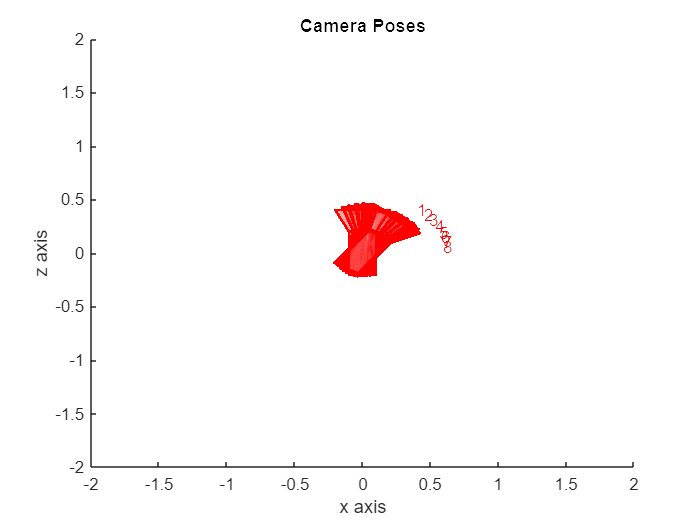

figure;
plotCamera(camPoses, Size=0.2);
view([0 0])
% Add labels to the x, y, and z axes
xlabel('x axis')
ylabel('y axis')
zlabel('z axis')
title('Camera Poses');

% Specify the viewing volume.
xlim([-2, 2]);
ylim([-2, 2]);
zlim([-2, 2]);

## 3D Stereo reconstruction from Disparity Map

This code reads a sequence of images from the specified directories and performs stereo rectification, disparity calculation, and 3D reconstruction on each pair of images. The resulting point cloud is denoised, transformed according to the camera pose, and displayed along with a plot of the camera pose. 

The loop iterates over the range of images, so it processes the images numbered 10 to `n_img+9`. The image files are named according to the pattern `'left_n.png'` and `'right_n.png'`, where `n` is the image number. 

For each iteration of the loop, the code reads the corresponding left and right images, rectifies them using the `rectifyStereoImages` function, and converts them to grayscale. It then applies histogram equalization to the grayscale images and calculates the disparity map using the `disparitySGM` function. 

The resulting disparity map is filtered to remove values outside the range 20-80, and the 3D scene is reconstructed using the `reconstructScene` function. The resulting point cloud is denoised, transformed according to the camera pose, and displayed using the `pcshow` function. The camera pose is also plotted using the `plotCamera` function.

figure;
view([5.77 -48.27])
title('Reconstructed Poinclod')
for n=10:n_img+9
    disp(string(n-9) + '/' + string(n_img) + ' images')
    frameLeft = imread('Scripts/images/Left_habitacion/left_' + string(n) +'.png'); 
    frameRight = imread('Scripts/images/Right_habitacion/right_' + string(n) + '.png');
    
    [frameLeftRect, frameRightRect, reprojectionMatrix] = ...
        rectifyStereoImages(frameLeft, frameRight, stereoParams);
    
    frameLeftGray  = rgb2gray(frameLeftRect);
    frameRightGray = rgb2gray(frameRightRect);
    
    imageLeftGrayHisteq = histeq(frameLeftGray);
    imageRightGrayHisteq = histeq(frameRightGray);
    
    disparityMap = disparitySGM(imageLeftGrayHisteq, imageRightGrayHisteq);
    disparityMap(disparityMap < 20) = NaN;
    disparityMap(disparityMap >80) = NaN;
    
    points3D = reconstructScene(disparityMap, reprojectionMatrix);
    
    % Convert to meters and create a pointCloud object
    points3D = points3D ./ 1000;
    ptCloud = pointCloud(points3D, 'Color', frameLeftRect);
    ptCloudOut = pcdenoise(ptCloud);
    
    tform = camPoses.AbsolutePose(n-9);
    ptCloudOut = pctransform(ptCloudOut, tform);
    pcshow(ptCloudOut)
    xlim([-2.5 2.5]);
    ylim([-1 2]);
    zlim([-0.5 5]);
    hold on
    plotCamera(camPoses(n-9,:), Size=0.2);
end

1/8 images
2/8 images
3/8 images
4/8 images
5/8 images
6/8 images
7/8 images
8/8 images


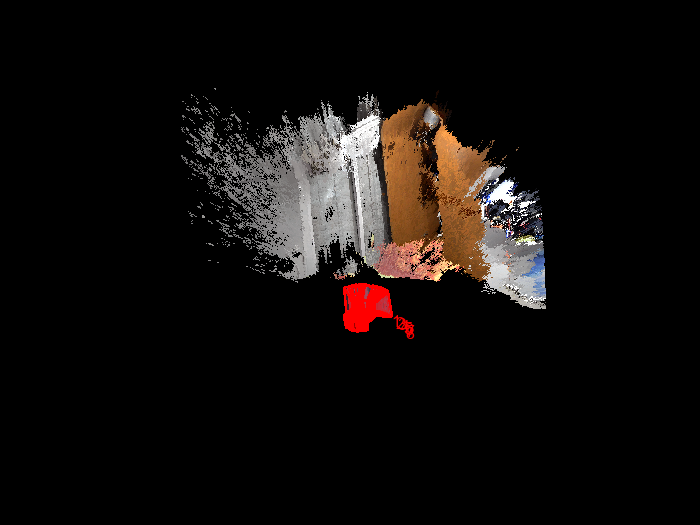

hold off
view([3.86 -56.18])

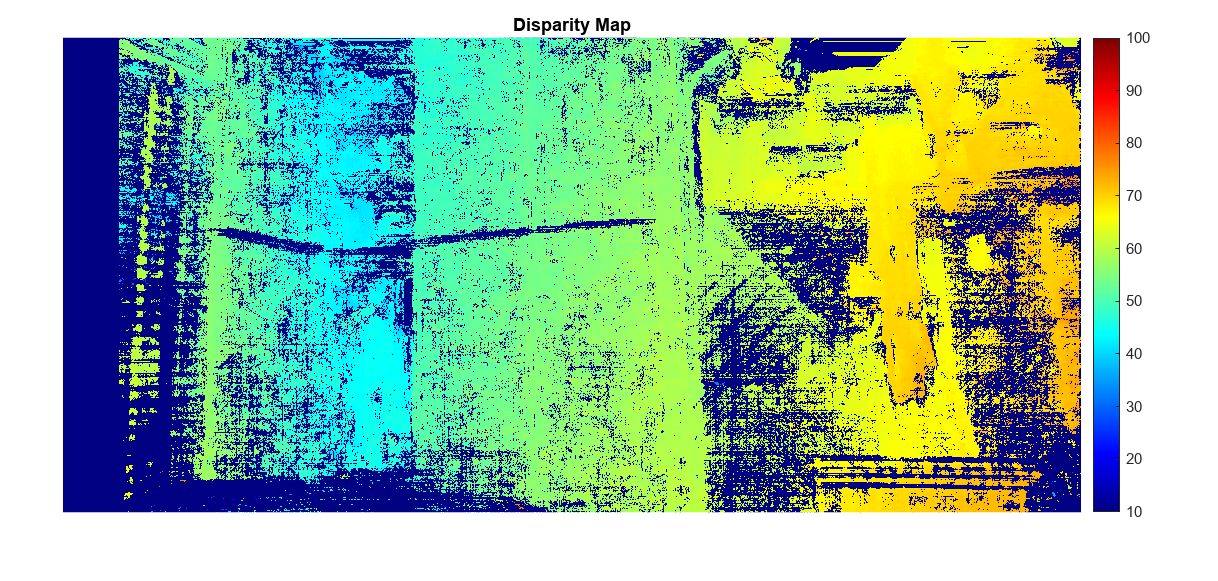

figure;
imshow(disparityMap, [10, 100]);
title('Disparity Map');
colormap jet
colorbar

## 3D Stereo reconstruction from feature matching triangulation

This section of the code performs feature detection and matching, triangulates the matched features to reconstruct the 3D structure of the scene, and finally visualizes the point cloud of the reconstructed scene. 

At each iteration of the loop, it then rectifies the stereo images using the `rectifyStereoImages` function and applies the SURF algorithm to detect and extract features from the rectified images. The features are matched between the left and right images, and the matched points are triangulated to reconstruct the 3D structure of the scene. The point cloud of the reconstructed scene is then transformed using the camera pose for that iteration and visualized. The cameras are also plotted on the visualization.

figure;
for n=10:n_img+9
    disp(string(n-9) + '/' + string(n_img) + ' images')
    
    frameLeft = imread('Scripts/images/Left_habitacion/left_' + string(n) +'.png'); 
    frameRight = imread('Scripts/images/Right_habitacion/right_' + string(n) + '.png');
    
    [frameLeftRect, frameRightRect, reprojectionMatrix] = rectifyStereoImages(frameLeft, frameRight, stereoParams);

    SURFpoints1 = detectSURFFeatures(rgb2gray(frameLeftRect));
    SURFpoints2 = detectSURFFeatures(rgb2gray(frameRightRect)); 

    [SURFfeatures1,SURFvalid_corners1] =extractFeatures(rgb2gray(frameLeftRect),SURFpoints1);
    [SURFfeatures2,SURFvalid_corners2] =extractFeatures(rgb2gray(frameRightRect),SURFpoints2);

    % Match the features between the images
    SURFindexPairs = matchFeatures(SURFfeatures1, SURFfeatures2);

    % Get the matching points in each image
    SURFmatchedPoints1 = SURFvalid_corners1(SURFindexPairs(:, 1), :);
    SURFmatchedPoints2 = SURFvalid_corners2(SURFindexPairs(:, 2), :);

    SURFpoint3d = triangulate(SURFmatchedPoints1, SURFmatchedPoints2, stereoParams);
    SURFmatchedPoints = vertcat(SURFmatchedPoints1, SURFmatchedPoints2);

    % Convert to meters and create a pointCloud object
    SURFpoint3d = SURFpoint3d./1000;
    % Create a point cloud
    pcSURF = pointCloud(SURFpoint3d);
    % Remove points that are too far away
    pcSURF = removeInvalidPoints(pcSURF);

    tform = camPoses.AbsolutePose(n-9);
    ptCloudOut = pctransform(pcSURF, tform);
    pcshow(ptCloudOut)
    xlim([-2.5 2.5]);
    ylim([-1 2]);
    zlim([-0.5 5]);
    hold on
    plotCamera(camPoses(n-9,:), Size=0.2);
end

1/8 images
2/8 images
3/8 images
4/8 images
5/8 images
6/8 images
7/8 images
8/8 images


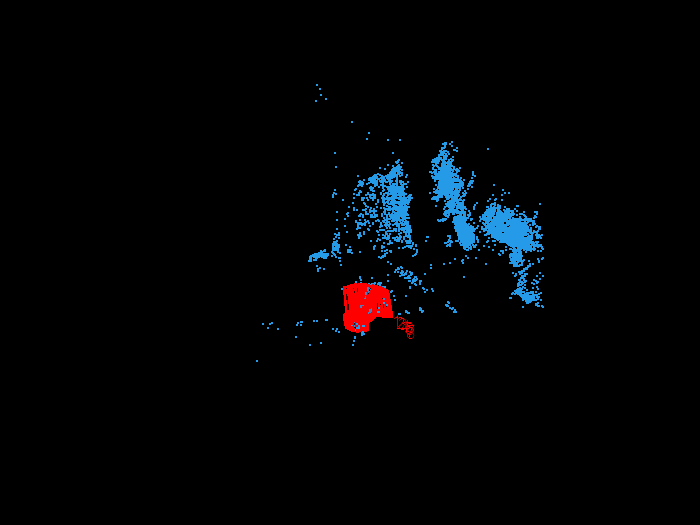

hold off
title('Reconstructed Poinclod')
view([3.86 -56.18])

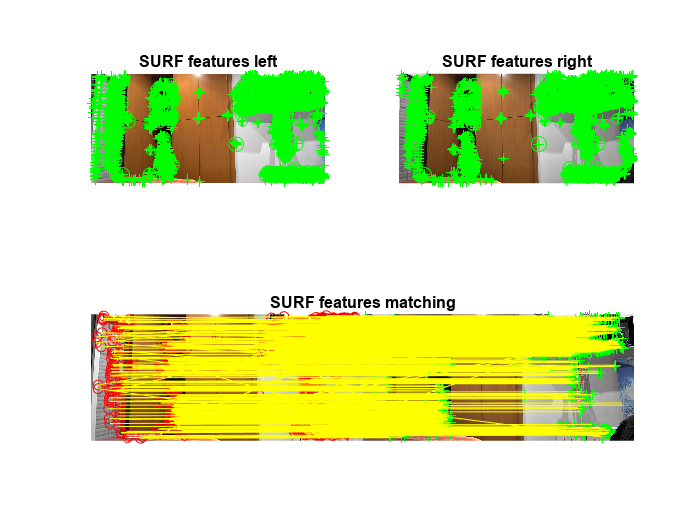

figure();
subplot(2,2,1)
imshow(frameLeftRect)
hold on
plot(SURFvalid_corners1); title('SURF features left')
subplot(2,2,2)
imshow(frameRightRect)
hold on
plot(SURFvalid_corners2); title('SURF features right')
subplot(2,2,3:4)
showMatchedFeatures(frameLeftRect,frameRightRect, SURFmatchedPoints1,SURFmatchedPoints2, 'Montage');
title('SURF features matching')

## Conclusions

As it can be seen the poincloud reconstruction from triangulatie features on both images is less dense, that is because the features are triangulated on the most significant part of the images in order to reduce the error in the matching. In this case the regions with more reliable features was the window, the clothes from the closet and the books from the shelf.

If the objective is to reconstruct large scenarios with a dense poincloud the disparity map reconstruction is the right choise. On the other hand if only a small object wants to be reconstructed with great precision maybe triangulate the poinclouds from different points of view could work if there are enough reliable features to track and triangulate.